## For $\rho_0\propto I_x$

clc;clear

S=load('Sx\MeanfieldSx');S=S.Expression1

S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9995    0.9995    0.9994    0.9993    0.9993    0.9992    0.9991    0.9990    0.9989    0.9988    0.9987    0.9986    0.9985    0.9984    0.9983    0.9982    0.9981    0.9979    0.9978    0.9977    0.9976    0.9975    0.9974    0.9972    0.9971    0.9970    0.9969    0.9967    0.9966    0.9965    0.9963    0.9962    0.9961    0.9960    0.9958    0.9957    0.9956    0.9954    0.9953    0

quench_time_seq=load('Sx\MeanfieldTime.mat','Expression1');quench_time_seq=quench_time_seq.Expression1;quench_time_seq=transpose(quench_time_seq)

quench_time_seq =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    1.0400    1.0800    1.1200    1.1600    1.2000    1.2400    1.2800    1.3200    1.3600    1.4000    1.4400    1.4800    1.5200    1.5600    1.6000    1.6400    1.6800    1.7200    1.7600    1.8000    1.8400    1.8800    1.9200    1.9600



end_point_seq=[320:10:400];
omega=zeros(length(end_point_seq),13);
lambda=zeros(length(end_point_seq),13);
cc=zeros(length(end_point_seq),13);
dd=zeros(length(end_point_seq),13);
omega_upper_bound=zeros(length(end_point_seq),13);
omega_lower_bound=zeros(length(end_point_seq),13);
lambda_upper_bound=zeros(length(end_point_seq),13);
lambda_lower_bound=zeros(length(end_point_seq),13);
contour_success=zeros(length(end_point_seq),13);
resnorm_all=zeros(length(end_point_seq),13);


predicted = @(aa,x) aa(3)*cos(2*pi*aa(1)*x+aa(4)).*exp(-2*pi*aa(2)*x);
% predicted = @(aa,x) aa(3)*cos(2*pi*aa(1)*x+0.5).*exp(-2*pi*aa(2)*x);
% quench_time_seq=(24*5*1e-3)*(0:40); %in ms

for jj=1:length(end_point_seq)
    for ii=1:13
        fprintf('Step ii:%d, jj:%d\n', ii, jj);
% for jj=1:5:27
%     for ii=6
        x=quench_time_seq(1:end_point_seq(jj));
        y=S(ii,1:end_point_seq(jj));
        options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
        grid=1000;
        if ii==1
        grid=1000;
        omega_near=linspace(-10*1e-3,10*1e-3,grid);
        lambda_near=linspace(-5*1e-3,5*1e-3,grid);
        a0 = [0.001;0.003;1;-0.];
        [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
        end
        if ii==2
            grid=1000;
            a0 = [0.001;0.003;1;-0];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-4,aa(1)+7e-4,grid);
            lambda_near=linspace(aa(2)-7e-4,aa(2)+7e-4,grid);
        end
        if ii==3
            grid=1000;
            a0 = [0.001;0.03;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
%             omega_near=linspace(aa(1)-1e-3,aa(1)+1e-3,grid);
%             lambda_near=linspace(aa(2)-1e-3,aa(2)+1e-3,grid);
            if jj==1 || ((jj>=6) && (jj<=9))  
                omega_near=linspace(aa(1)-1e-3,aa(1)+1e-3,grid);
                lambda_near=linspace(aa(2)-1e-3,aa(2)+1e-3,grid);
            elseif jj >= 10 || jj == 2
                omega_near=linspace(aa(1)-8e-3,aa(1)+8e-3,grid);
                lambda_near=linspace(aa(2)-8e-3,aa(2)+8e-3,grid);
            else
                omega_near=linspace(aa(1)-8e-3,aa(1)+8e-3,grid);
                lambda_near=linspace(aa(2)-8e-3,aa(2)+8e-3,grid);
            end
        end
        if ii==4
            grid=1000;
            a0 = [0.001;0.03;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-3,aa(1)+7e-3,grid);
            lambda_near=linspace(aa(2)-7e-3,aa(2)+7e-3,grid);
        end
        if ii==5
            grid=1000;
            a0 = [0.001;0.1;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-3,aa(1)+7e-3,grid);
            lambda_near=linspace(aa(2)-7e-3,aa(2)+7e-3,grid);
        end
        if ii>=6 && ii<=11
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.01,aa(1)+0.01,grid);
            lambda_near=linspace(aa(2)-0.01,aa(2)+0.01,grid);
        end
        if ii==12
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.05,aa(1)+0.05,grid);
            lambda_near=linspace(aa(2)-0.05,aa(2)+0.05,grid);
        end
        if ii==13
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.05,aa(1)+0.05,grid);
            lambda_near=linspace(aa(2)-0.05,aa(2)+0.05,grid);
        end

        omega(jj,ii)=aa(1); %in kHz
        lambda(jj,ii)=aa(2); %in kHz
        cc(jj,ii)=aa(3);
        dd(jj,ii)=aa(4);

        resnorm_all(jj,ii)=resnorm;

%         figure()
%         y_fit=aa(3)*cos(2*pi*aa(1)*x+aa(4)).*exp(-2*pi*aa(2)*x);
%         % y_fit=aa(3)*cos(2*pi*aa(1)*x+0.5).*exp(-2*pi*aa(2)*x);
%         plot(x,y,'o',x,y_fit,'-')

### 画出resnorm的等高线图

        ydata=omega_near;
        xdata=lambda_near;
        resnorm_near=zeros(length(xdata),length(ydata));
        for i=1:length(ydata)
            for j=1:length(xdata)
                y_near=aa(3)*cos(2*pi*omega_near(i)*x+aa(4)).*exp(-2*pi*lambda_near(j)*x);
                % y_near=aa(3)*cos(2*pi*omega_near(i)*x+0.5).*exp(-2*pi*lambda_near(j)*x);
                resnorm_near(i,j)=sum((y_near-y).^2);
            end
        end

        % figure()
        % [xxdata,yydata]=meshgrid(xdata,ydata);
        % mesh(xxdata,yydata,(resnorm_near-resnorm)/resnorm)
        % ylabel('\omega')
        % xlabel("\lambda")
        % zlabel('sum of square of residues')

        p=0.95;
        nu1=2; %number of free parameters
        nu2=length(y)-length(aa);
        delta_resnorm=finv(p,nu1,nu2)*nu1/nu2;

%        
        M=contourc(xdata,ydata,(resnorm_near-resnorm)/resnorm,[delta_resnorm,delta_resnorm]); %not show contour

%         figure()
%         [M]=contour(xdata,ydata,(resnorm_near-resnorm)/resnorm,[delta_resnorm,delta_resnorm]); %show contour
%         ylabel('\omega')
%         xlabel("\lambda")


        if ii == 1
            omega_upper_bound(jj,ii)=0.0;
            omega_lower_bound(jj,ii)=0.0;
            lambda_upper_bound(jj,ii)=0.0;
            lambda_lower_bound(jj,ii)=0.0;
            
            contour_success(jj,ii)=1;
        else
            
            MM=M(2,:);
            [contour_index]=find(M(1,:)==delta_resnorm);
            [~,right_contour]=min(abs(MM(contour_index+1)-aa(1))); %pick the right contour
            right_index=contour_index(right_contour);
            num_points=MM(right_index);
            contour_success(jj,ii)=(num_points==length(M(2,right_index+1:right_index+num_points)));
            if contour_success == 0
                fprintf('Fail at: ii:%d, jj:%d\n', ii, jj);
            end
            omega_upper_bound(jj,ii)=max(M(2,right_index+1:right_index+num_points),[],2);
            omega_lower_bound(jj,ii)=min(M(2,right_index+1:right_index+num_points),[],2);
            lambda_upper_bound(jj,ii)=max(M(1,right_index+1:right_index+num_points),[],2);
            lambda_lower_bound(jj,ii)=min(M(1,right_index+1:right_index+num_points),[],2);
        end
    end
end

Step ii:1, jj:1



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:2, jj:1



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:1



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:5, jj:1



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:1



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:2



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:2



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:2



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:2



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:5, jj:2



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:2



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:3



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:3



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:3



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:3



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:5, jj:3



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:3



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:4



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:4



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:4



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:4



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:5, jj:4



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:4



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:5



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:3, jj:5



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:5



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:5, jj:5



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:5



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:6



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:6



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:6



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:6



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:5, jj:6



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:6



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:7



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:7



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:3, jj:7



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:5, jj:7



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:7



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:8



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:8



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:8



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:8



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:5, jj:8



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:8



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:1, jj:9



Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


Step ii:2, jj:9



Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


Step ii:3, jj:9



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:4, jj:9



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:5, jj:9



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 8.000000e+02.



Step ii:6, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:7, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:8, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:9, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:10, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:11, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:12, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:13, jj:9



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


clear resnorm_near

[j,i]=find(contour_success==0) %check the number of points on the contour


j =

  空的 0×1 double 列向量


i =

  空的 0×1 double 列向量



figure()
xi=-0.4:0.05:0.2;
lower_bar=omega-omega_lower_bound;
upper_bar=omega_upper_bound-omega;

% errorbar(xi,transpose(omega),transpose(lower_bar),transpose(upper_bar),'-o')
errorbar(xi,mean(omega),max(lower_bar),max(upper_bar),'-o')
fprintf('%f,',mean(omega));fprintf('\n');

0.000000,0.000544,0.003281,0.001271,0.011153,0.028241,0.058717,0.073041,0.083142,0.093179,0.104690,0.114015,0.118377,


fprintf('%f,',max(lower_bar));fprintf('\n');

0.000001,0.000471,0.000098,0.004167,0.000561,0.001136,0.000498,0.000318,0.000255,0.000297,0.000556,0.000958,0.001020,


fprintf('%f,',max(upper_bar));fprintf('\n');

0.000000,0.000498,0.000100,0.005871,0.000533,0.001098,0.000495,0.000317,0.000255,0.000297,0.000554,0.000952,0.001013,


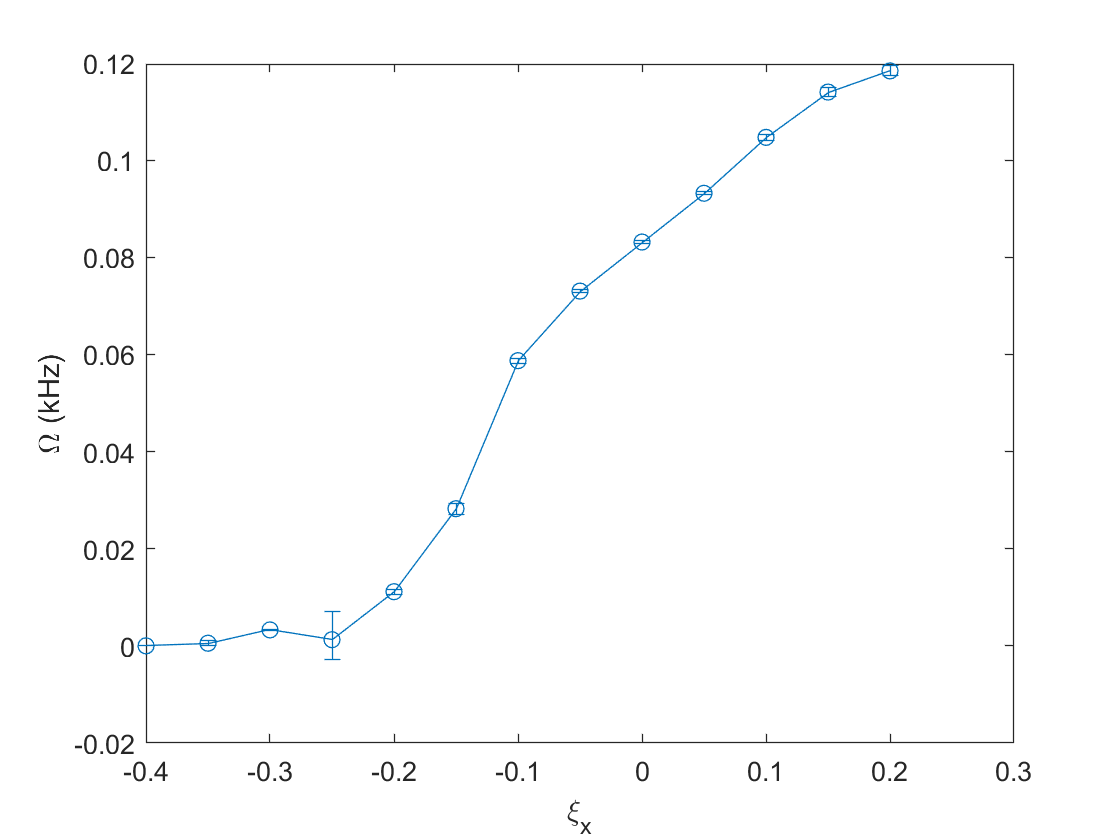

% errorbar(xi,omega,lower_bar,upper_bar)
xlabel('\xi_x')
ylabel('\Omega (kHz)')

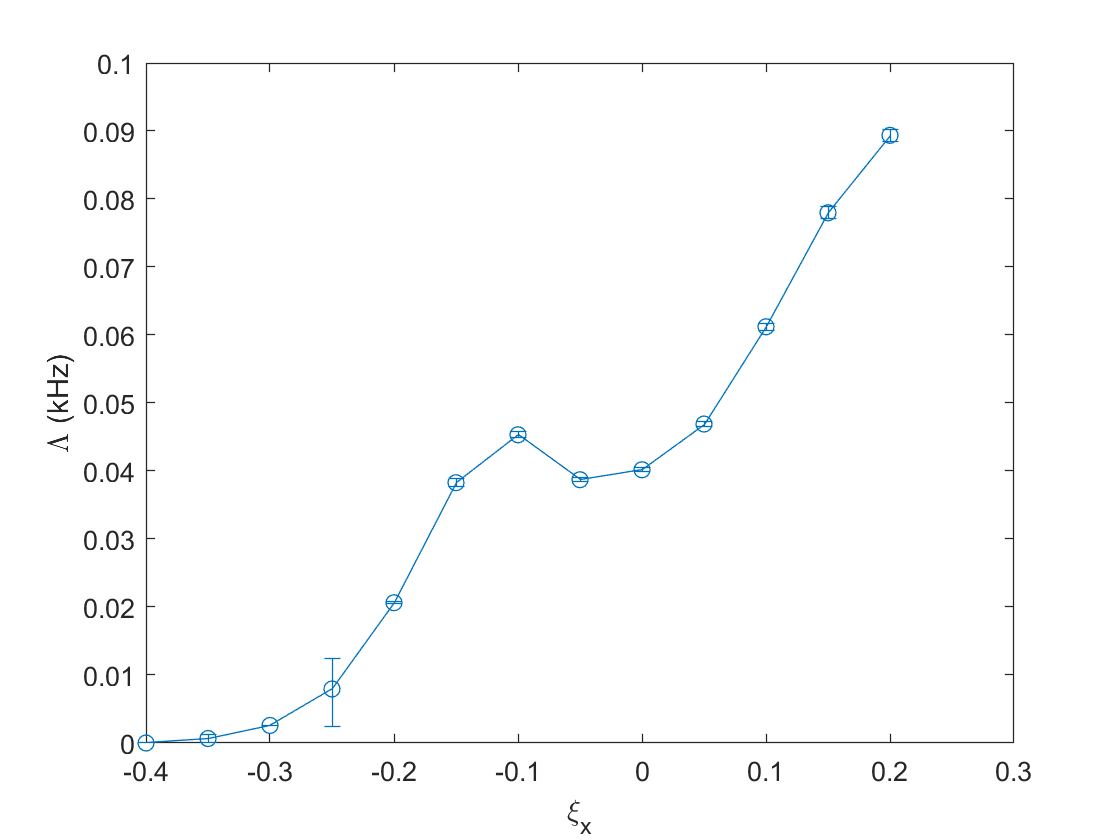

% legend('15 fitting points','41 fitting points','box','off')

figure()
lower_bar=lambda-lambda_lower_bound;
upper_bar=lambda_upper_bound-lambda;
errorbar(xi,mean(lambda),max(lower_bar),max(upper_bar),'-o')
% errorbar(xi,lambda,lower_bar,upper_bar,'-o')
% errorbar(xi,lambda,lower_bar,upper_bar)
xlabel('\xi_x')
ylabel('\Lambda (kHz)')

fprintf('%f,',mean(lambda));fprintf('\n');

0.000000,0.000657,0.002580,0.007944,0.020630,0.038279,0.045328,0.038717,0.040180,0.046906,0.061208,0.077971,0.089365,


fprintf('%f,',max(lower_bar));fprintf('\n');

0.000001,0.000542,0.000016,0.005510,0.000146,0.000556,0.000417,0.000324,0.000267,0.000302,0.000544,0.000871,0.000879,


fprintf('%f,',max(upper_bar));fprintf('\n');

0.000000,0.000537,0.000016,0.004410,0.000140,0.000564,0.000421,0.000328,0.000270,0.000305,0.000551,0.000884,0.000890,


% legend('15 fitting points','41 fitting points','box','off')


figure()
xi=-0.4:0.05:0.2;
plot(xi,omega,'-o')
find(omega(:,6)<0.01)


ans =

  空的 0×1 double 列向量



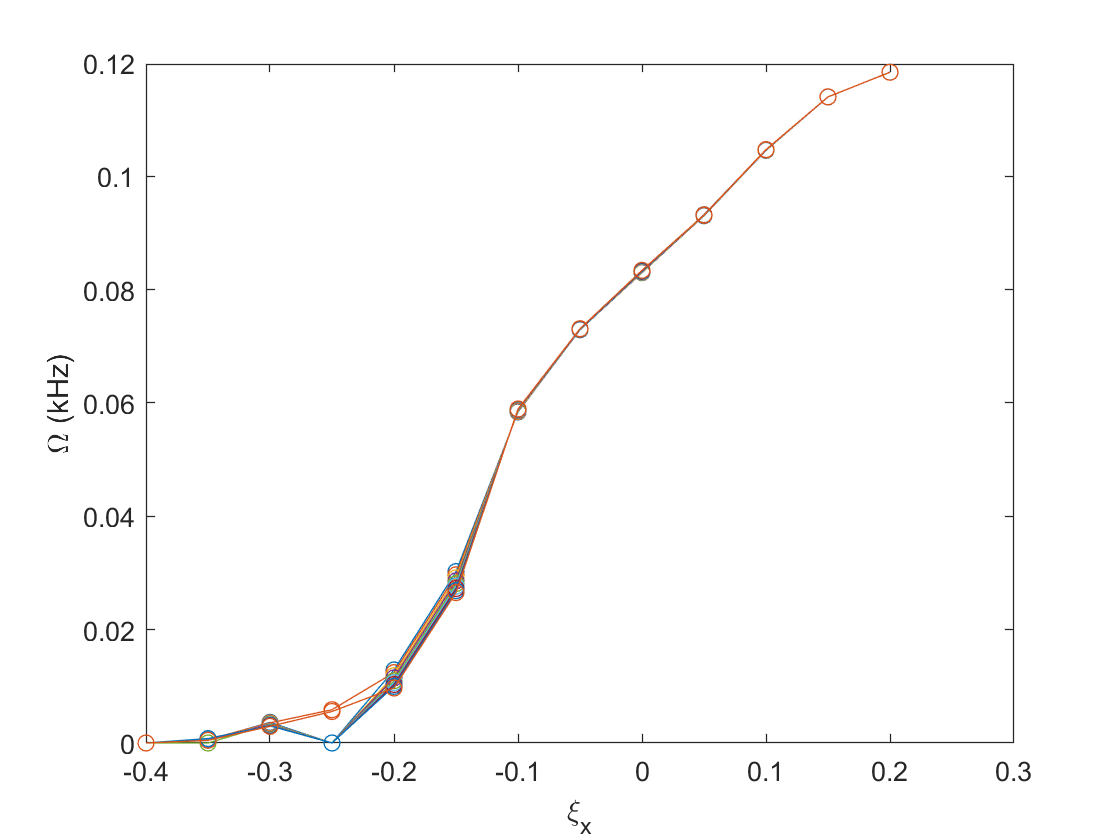

xlabel('\xi_x')
ylabel('\Omega (kHz)')

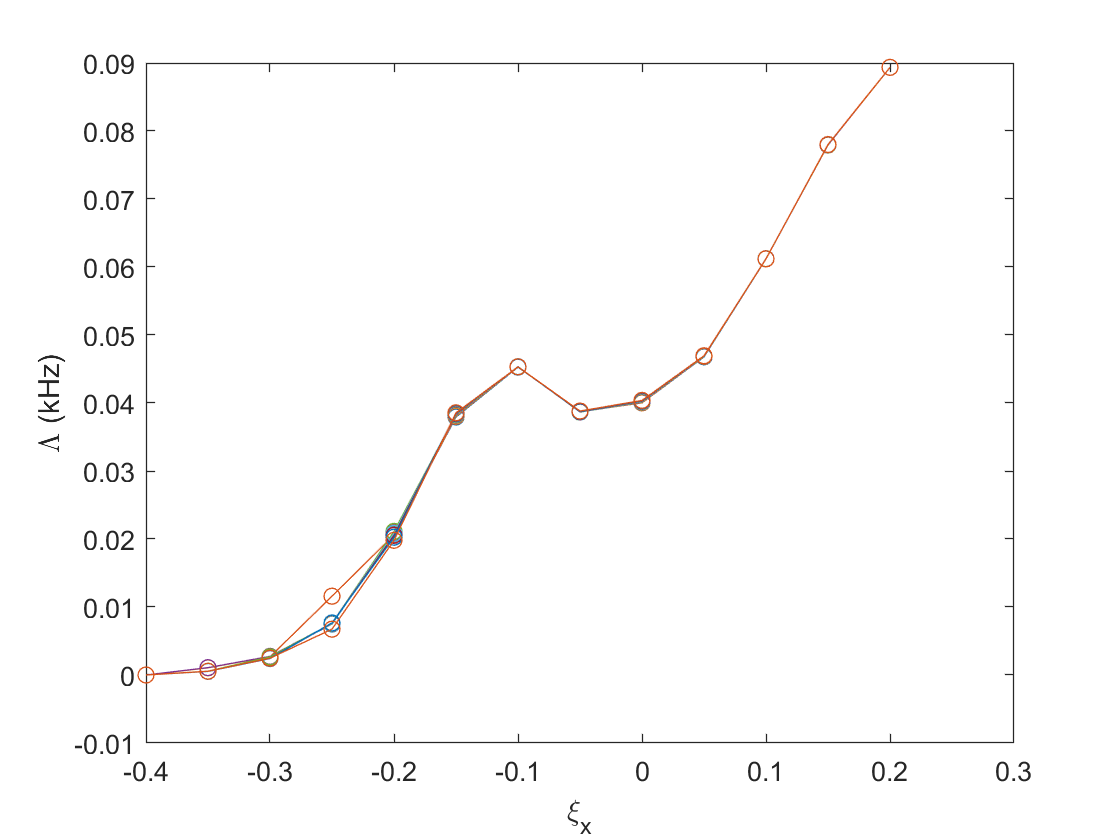

figure()
plot(xi,lambda,'-o')
xlabel('\xi_x')
ylabel('\Lambda (kHz)')

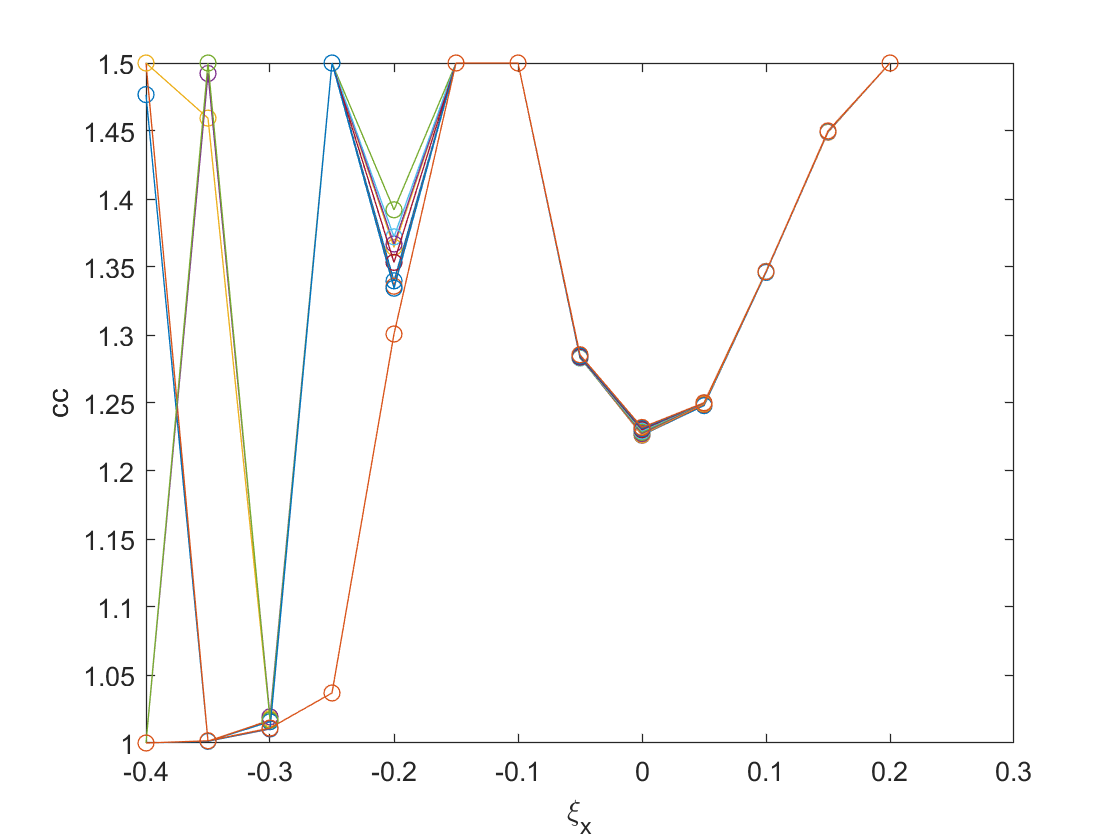

figure()
plot(xi,cc,'-o')
xlabel('\xi_x')
ylabel('cc')

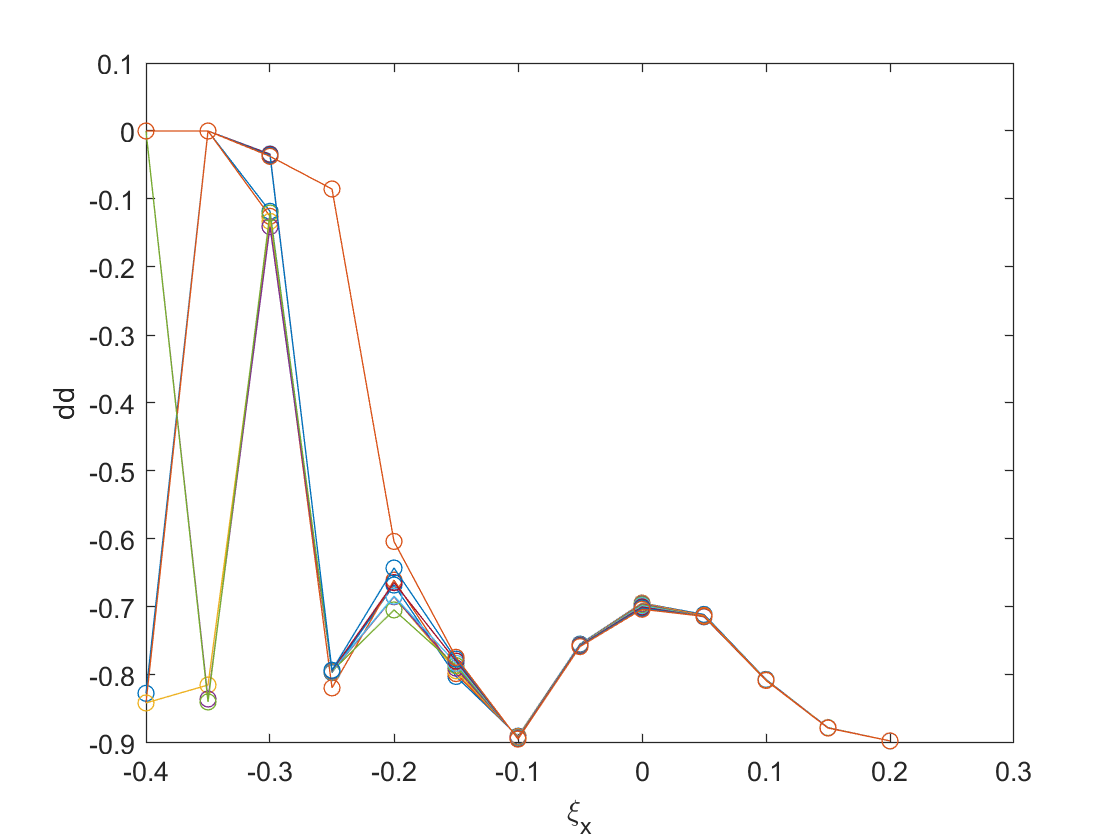

figure()
plot(xi,dd,'-o')
xlabel('\xi_x')
ylabel('dd')

looking into the sum of squares of residues

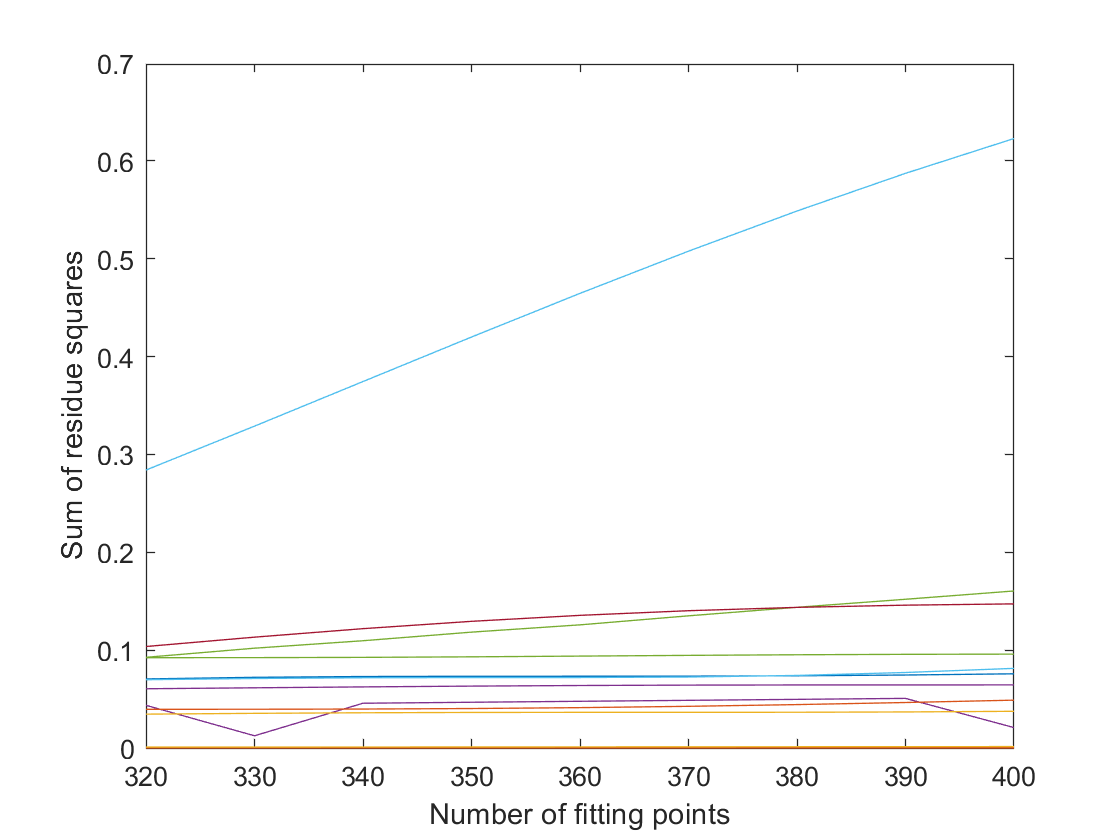

figure()
plot(end_point_seq, resnorm_all)
xlabel('Number of fitting points')
ylabel('Sum of residue squares')

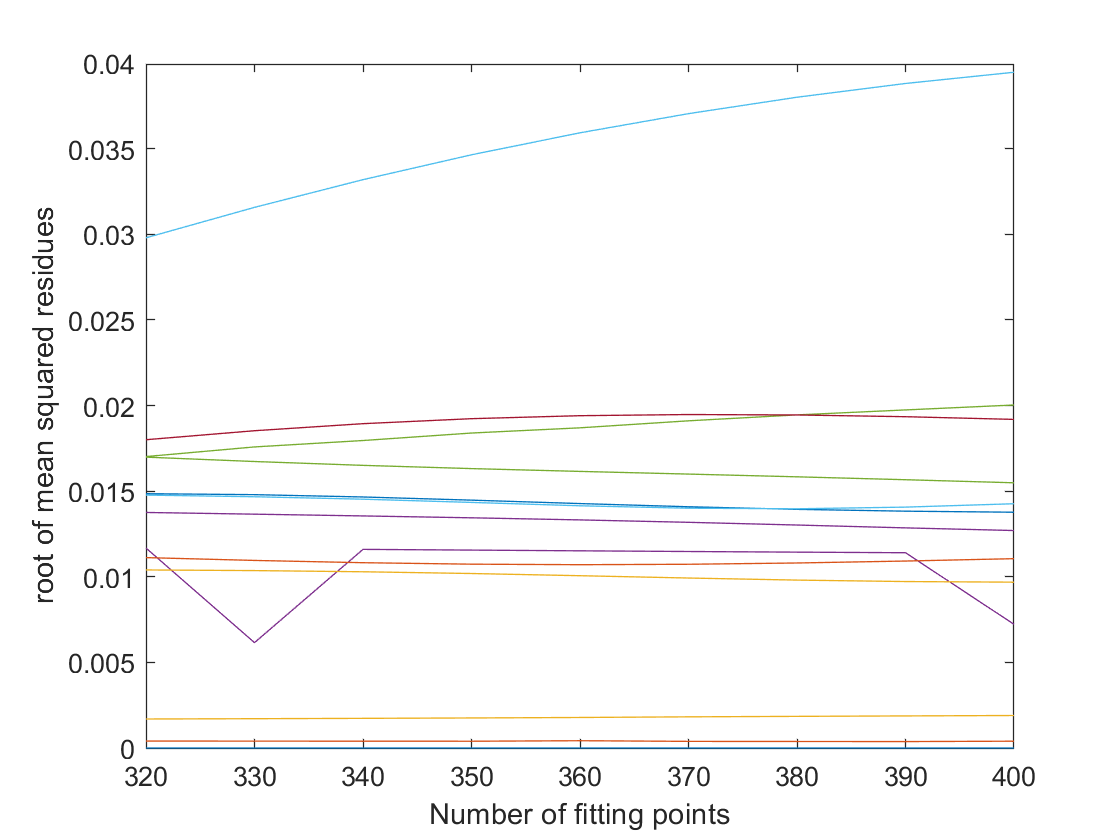

figure()
plot(end_point_seq, sqrt(resnorm_all./end_point_seq'))
xlabel('Number of fitting points')
ylabel('root of mean squared residues')

 保存变量

save('Sx\Meanfield_resnorm_all.mat','resnorm_all')
save('Sx\Meanfield_omega.mat','omega')
save('Sx\Meanfield_omega_lower_bound.mat','omega_lower_bound')
save('Sx\Meanfield_omega_upper_bound.mat','omega_upper_bound')
save('Sx\Meanfield_lambda.mat','lambda')
save('Sx\Meanfield_lambda_lower_bound.mat','lambda_lower_bound')
save('Sx\Meanfield_lambda_upper_bound.mat','lambda_upper_bound')
save('Sx\Meanfield_cc.mat','cc')
save('Sx\Meanfield_dd.mat','dd')

Load变量

% lambda=load('Sx\Meanfield_lambda.mat').lambda;
% lambda_lower_bound=load('Sx\Meanfield_lambda_lower_bound.mat').lambda_lower_bound;
% lambda_upper_bound=load('Sx\Meanfield_lambda_upper_bound.mat').lambda_upper_bound;